# **NUNNA LEEKHITH SRI KRISHNA**

## Climate-Aware Adaptation Strategy Prediction Using Machine Learning

#### **Objective:**

#### Develop a machine learning model that predicts the most suitable **agricultural adaptation strategy** based on climate, environmental, and regional factors.

#### This can help farmers or policy-makers **automatically choose the best strategy** to improve crop resilience and yield under changing climate conditions.

**Size and Feactures of Dataset**

% Load dataset
data = readtable("C:\Users\leekh\OneDrive - Amrita vishwa vidyapeetham\Git\5_climate_change_impact_on_agriculture_2024\climate_change_impact_on_agriculture_2024.csv")

data = 10000×15 table
    Year       Country             Region             Crop_Type       Average_Temperature_C    Total_Precipitation_mm    CO2_Emissions_MT    Crop_Yield_MT_per_HA    Extreme_Weather_Events    Irrigation_Access_    Pesticide_Use_KG_per_HA    Fertilizer_Use_KG_per_HA    Soil_Health_Index       Adaptation_Strategies       Economic_Impact_Million_USD
    ____    _____________    ___________________    ______________    _____________________    ______________________    ________________    ____________________    ______________________    __________________


% Size of dataset
[m, n] = size(data);
fprintf('Rows: %d, Columns: %d\n', m, n);

Rows: 10000, Columns: 15



% List all feature names
disp('Feature Names:');

Feature Names:


disp(data.Properties.VariableNames');

    {'Year'                       }
    {'Country'                    }
    {'Region'                     }
    {'Crop_Type'                  }
    {'Average_Temperature_C'      }
    {'Total_Precipitation_mm'     }
    {'CO2_Emissions_MT'           }
    {'Crop_Yield_MT_per_HA'       }
    {'Extreme_Weather_Events'     }
    {'Irrigation_Access_'         }
    {'Pesticide_Use_KG_per_HA'    }
    {'Fertilizer_Use_KG_per_HA'   }
    {'Soil_Health_Index'          }
    {'Adaptation_Strategies'      }
    {'Economic_Impact_Million_USD'}



**Class Distribution**

*Read the Dataset*

% Load the CSV dataset
data = readtable('C:\Users\leekh\OneDrive - Amrita vishwa vidyapeetham\Git\5_climate_change_impact_on_agriculture_2024\climate_change_impact_on_agriculture_2024.csv');

*Convert Target Column to Categorical*

% Convert the target column to categorical if it isn’t already
data.Adaptation_Strategies = categorical(data.Adaptation_Strategies);

*Get Class Counts*

% Count number of samples per strategy
strategyCounts = countcats(data.Adaptation_Strategies);

% Get the strategy names
strategyNames = categories(data.Adaptation_Strategies);

*Display Class Distribution*

% Print the results
fprintf('Adaptation Strategy Distribution:\n');

Adaptation Strategy Distribution:


for i = 1:length(strategyNames)
    fprintf('%s: %d samples\n', strategyNames{i}, strategyCounts(i));
end

Crop Rotation: 1957 samples
Drought-resistant Crops: 1995 samples
No Adaptation: 2024 samples
Organic Farming: 1975 samples
Water Management: 2049 samples


*Stacked Histogram*

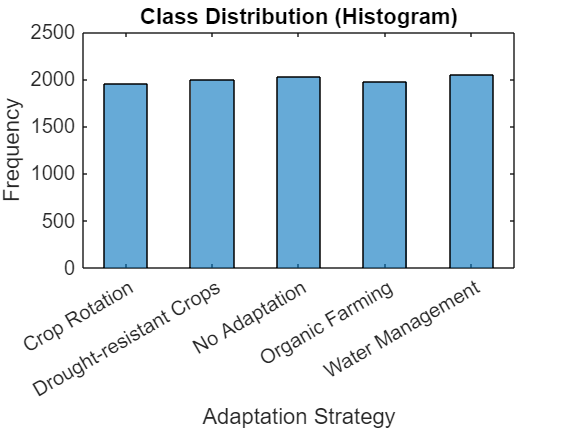

figure;
histogram(data.Adaptation_Strategies, 'DisplayStyle','bar', 'BarWidth',0.5);
xlabel('Adaptation Strategy');
ylabel('Frequency');
title('Class Distribution (Histogram)');

*Donut Chart*

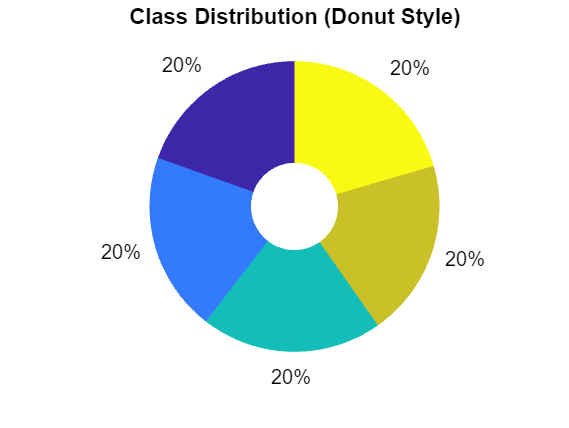

figure;
p = pie(strategyCounts);
title('Class Distribution (Donut Style)');
% Create hole
for i = 1:2:length(p)
    p(i).EdgeColor = 'none';
end
% Place white circle in center
hold on;
r = rectangle('Position',[-0.3,-0.3,0.6,0.6], 'Curvature',[1,1], 'FaceColor','white', 'EdgeColor','none');
hold off;

**Preprocessing for Classification**

*Load the Dataset*

% Read the dataset from CSV
data = readtable("C:\Users\leekh\OneDrive - Amrita vishwa vidyapeetham\Git\5_climate_change_impact_on_agriculture_2024\climate_change_impact_on_agriculture_2024.csv")

data = 10000×15 table
    Year       Country             Region             Crop_Type       Average_Temperature_C    Total_Precipitation_mm    CO2_Emissions_MT    Crop_Yield_MT_per_HA    Extreme_Weather_Events    Irrigation_Access_    Pesticide_Use_KG_per_HA    Fertilizer_Use_KG_per_HA    Soil_Health_Index       Adaptation_Strategies       Economic_Impact_Million_USD
    ____    _____________    ___________________    ______________    _____________________    ______________________    ________________    ____________________    ______________________    __________________

*Convert Relevant Columns to Categorical*

% Convert string-based columns to categorical
data.Country = categorical(data.Country);
data.Region = categorical(data.Region);
data.Crop_Type = categorical(data.Crop_Type);
data.Adaptation_Strategies = categorical(data.Adaptation_Strategies); % This is our target

*Handle Missing Data*

% Show summary of missing values
disp('Missing value count per column:');

Missing value count per column:


disp(sum(ismissing(data)));

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0




% Option 1: Drop rows with missing values
data = rmmissing(data);

% (Option 2: Fill missing values — e.g., fill numeric with mean)
% data.Average_Temperature_C = fillmissing(data.Average_Temperature_C, 'movmean', 5);

*Encode Categorical Features*

% Label encode categorical variables
data.Region = grp2idx(data.Region);
data.Country = grp2idx(data.Country);
data.Crop_Type = grp2idx(data.Crop_Type);

*Extract Features (X) and Labels (Y)*

% Select features and label
X = data(:, {'Average_Temperature_C', 'Total_Precipitation_mm', ...
             'CO2_Emissions_MT', 'Extreme_Weather_Events', ...
             'Irrigation_Access_', 'Soil_Health_Index', ...
             'Crop_Type', 'Region'});  % Feel free to include Country too

Y = data.Adaptation_Strategies;

*Convert Table to Matrix & Normalize Features*

% Convert table to matrix and normalize features
X = normalize(table2array(X));  % Z-score normalization

*Encode the Target Labels*

% Convert the categorical target into numeric class labels
Y = grp2idx(Y);

*Split into Train & Test Sets*

% Create a partition (70% train, 30% test)
cv = cvpartition(size(X,1), 'HoldOut', 0.3);

XTrain = X(training(cv), :);
YTrain = Y(training(cv));
XTest = X(test(cv), :);
YTest = Y(test(cv));

*Convert Training and Test Data into Tables*

% Combine XTrain and YTrain into one table
trainTable = array2table([XTrain YTrain], ...
    'VariableNames', {'AvgTemp', 'Precip', 'CO2', 'ExtremeEvents', ...
                      'Irrigation', 'SoilHealth', 'CropType', 'Region', 'Strategy'});

% Combine XTest and YTest into one table
testTable = array2table([XTest YTest], ...
    'VariableNames', {'AvgTemp', 'Precip', 'CO2', 'ExtremeEvents', ...
                      'Irrigation', 'SoilHealth', 'CropType', 'Region', 'Strategy'});

*Write the tables to CSV files*

writetable(trainTable, 'train_data.csv');
writetable(testTable, 'test_data.csv');

disp("✅ Train and test sets saved as 'train_data.csv' and 'test_data.csv'");

✅ Train and test sets saved as 'train_data.csv' and 'test_data.csv'


**Quality Check Before Training ML Model**

*Check for Missing Values*

disp("Missing values per column:");

Missing values per column:


disp(sum(ismissing(data)));

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



*Check Class Distribution (Again)*

tabulate(Y)  % shows class count, percentage

  Value    Count   Percent
      1     1957     19.57%
      2     1995     19.95%
      3     2024     20.24%
      4     1975     19.75%
      5     2049     20.49%


*Check Feature Statistics*

disp("Mean of features (should be ~0 after normalization):");

Mean of features (should be ~0 after normalization):


disp(mean(X));

   1.0e-14 *

   -0.0442    0.1432   -0.0217    0.0122    0.0638   -0.0956   -0.0069    0.0399




disp("Std deviation of features (should be ~1):");

Std deviation of features (should be ~1):


disp(std(X));

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



*Correlation Heatmap*

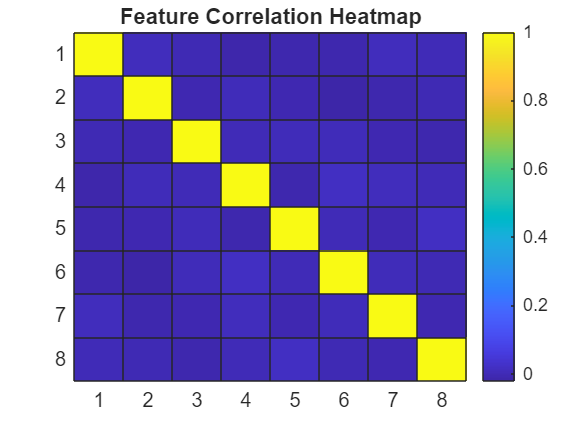

figure;
corrMatrix = corr(X);
heatmap(corrMatrix, 'Colormap', parula, 'Title', 'Feature Correlation Heatmap');

*Outlier Visualization (Optional)*

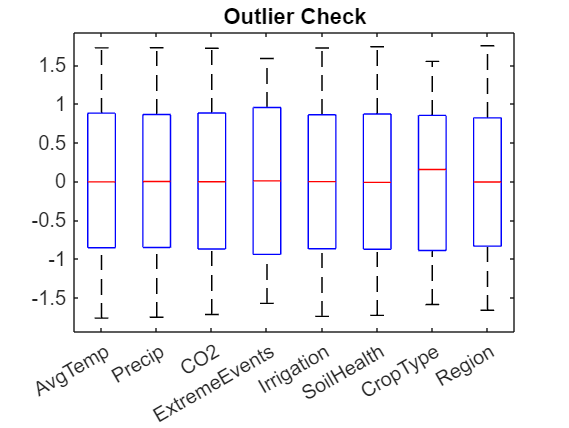

figure;
boxplot(X, 'Labels', {'AvgTemp', 'Precip', 'CO2', 'ExtremeEvents', ...
                      'Irrigation', 'SoilHealth', 'CropType', 'Region'});
title('Outlier Check');

**Compare 5 Classifiers + Accuracy Leaderboard**

% ==================== Setup ====================
models = {
    fitcecoc(XTrain, YTrain),           'SVM (ECOC)';
    fitcknn(XTrain, YTrain),            'KNN';
    fitctree(XTrain, YTrain),           'Decision Tree';
    fitcensemble(XTrain, YTrain),       'Random Forest';
    fitcnb(XTrain, YTrain),             'Naive Bayes';
};


% Initialize results storage
accuracies = zeros(size(models, 1), 1);

% ==================== Train & Evaluate ====================
for i = 1:size(models, 1)
    model = models{i,1};
    name = models{i,2};
    
    % Predict on test set
    predictions = predict(model, XTest);
    
    % Calculate accuracy
    acc = sum(predictions == YTest) / numel(YTest);
    accuracies(i) = acc;
    
    % Display individual result
    fprintf('✅ %s Accuracy: %.2f%%\n', name, acc * 100);
end

✅ SVM (ECOC) Accuracy: 19.67%
✅ KNN Accuracy: 18.93%
✅ Decision Tree Accuracy: 18.90%
✅ Random Forest Accuracy: 18.73%
✅ Naive Bayes Accuracy: 19.03%



% ==================== Leaderboard ====================
% Display as sorted leaderboard
[sortedAcc, idx] = sort(accuracies, 'descend');
sortedNames = models(idx, 2);

fprintf('\n🏆 Accuracy Leaderboard:\n');


🏆 Accuracy Leaderboard:


for i = 1:length(sortedAcc)
    fprintf('%d. %s - %.2f%%\n', i, sortedNames{i}, sortedAcc(i) * 100);
end

1. SVM (ECOC) - 19.67%
2. Naive Bayes - 19.03%
3. KNN - 18.93%
4. Decision Tree - 18.90%
5. Random Forest - 18.73%


**Repair the data**

*Labels Might Not Be Properly Encoded*

unique(YTrain)

ans =      1
     2
     3
     4
     5


*Features Might Be Useless for Classification*

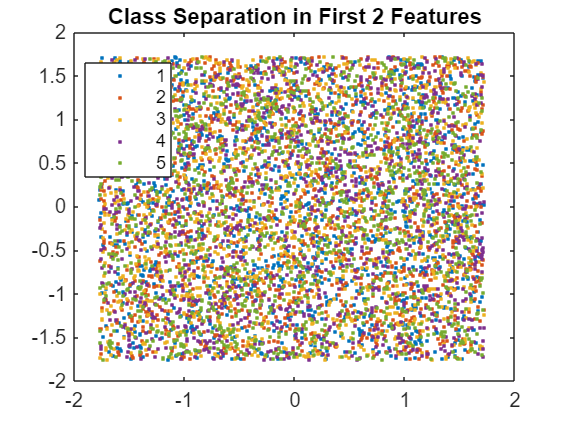

gscatter(XTrain(:,1), XTrain(:,2), YTrain);
title("Class Separation in First 2 Features");

*Model Complexity Needs Tuning*

% Tune Random Forest
rf = fitcensemble(XTrain, YTrain, 'NumLearningCycles', 100);

% Tune KNN
knn = fitcknn(XTrain, YTrain, 'NumNeighbors', 7);

% Tune SVM (ECOC + linear kernel)
svm = fitcecoc(XTrain, YTrain, 'Learners', templateSVM('KernelFunction','linear'));

*Convert Labels to Numeric (If Not Already)*

YTrain = grp2idx(YTrain);
YTest = grp2idx(YTest);

*Upgrade Random Forest*

rfModel = fitcensemble(XTrain, YTrain, ...
    'NumLearningCycles', 200, ...
    'Method', 'Bag');
YPred = predict(rfModel, XTest);
acc = sum(YPred == YTest) / numel(YTest);
fprintf("🔥 Upgraded RF Accuracy: %.2f%%\n", acc*100);

🔥 Upgraded RF Accuracy: 20.17%


*Feature Selection*

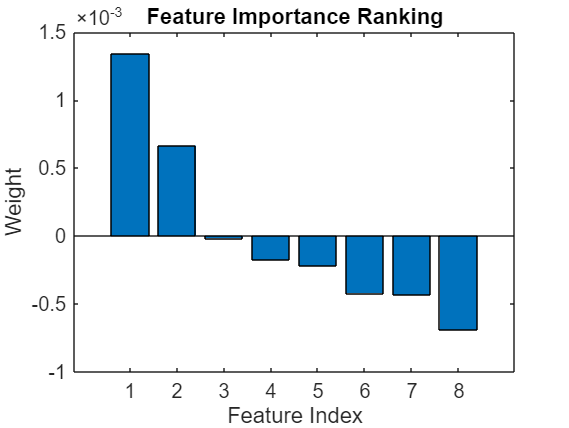

% Rank features using reliefF
[idx, weights] = relieff(XTrain, YTrain, 10);
bar(weights(idx));
title('Feature Importance Ranking');
xlabel('Feature Index');
ylabel('Weight');


% Use top N features (e.g., 5)
XTrainTop = XTrain(:, idx(1:5));
XTestTop = XTest(:, idx(1:5));

🚫 **Classification is not a good fit** for this dataset **in its current form**.

That's It